# Procedure 2 for Acrobot system

clear; close all; clc;
set(0,'DefaultLineLineWidth',2.5)
set(0,'defaultfigurecolor',[1 1 1])

## 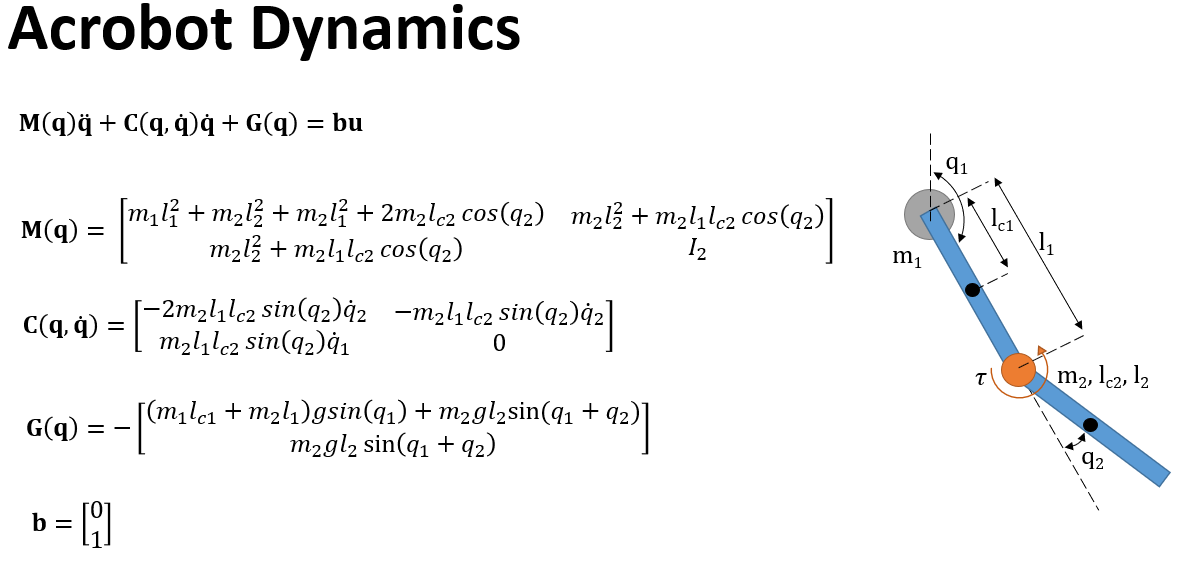

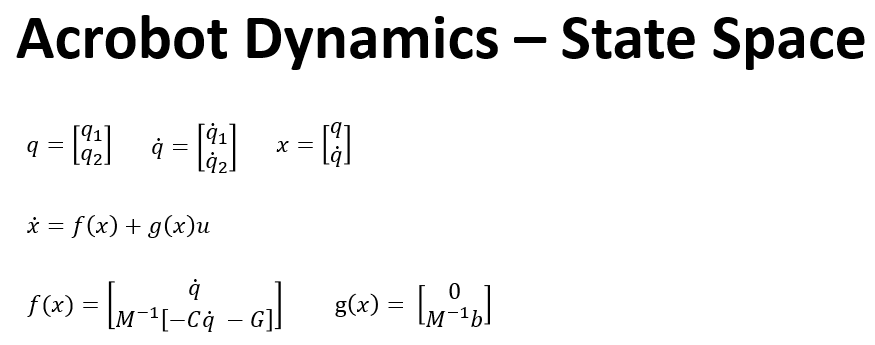

f = @Acrobot_F; %f(t,x,u)
fu = @Acrobot_g; %only g(t,x)

## Plot the uncontrolled response

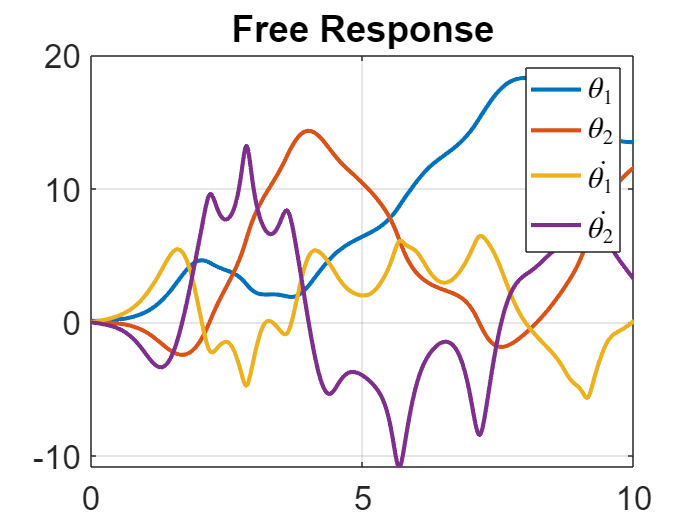

n=4; % dimension
tSpan = 0:0.02:10; ic = [0.1,0,0,0]';
options = odeset('RelTol',1e-9,'AbsTol',1e-300);
[T, x_uncontrolled] = ode45(@(t,x)f(0, x, 0), tSpan, ic,options);
close all
figure()
%subplot(1,2,1)
plot(T, x_uncontrolled(:,1:n))
grid on;
title('Free Response')
set(gca,'fontsize',20)
LEG = legend('$\theta_1$', '$\theta_2$', '$\dot{\theta_1}$','$\dot{\theta_2}$');
set(LEG,'interpreter','latex');

## 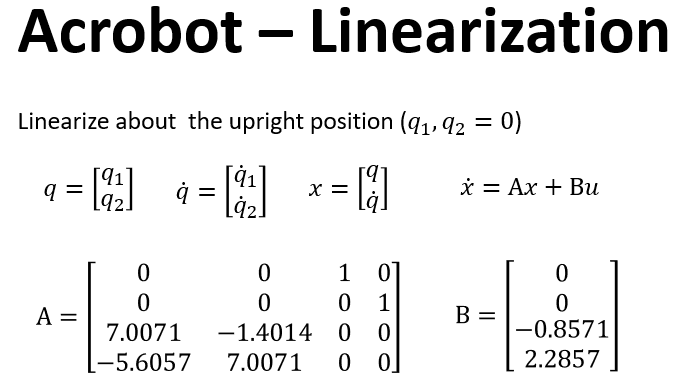

x = sym('x',[n;1]);
u = sym('u',[1;1]);
x0 = [0;0;0;0];

A0 = double(subs(jacobian(f(0,x,0),x),x,x0)); 
g0 = double(subs(jacobian(f(0,x0,u),u),u,0));

## Construct the Hamiltonain system

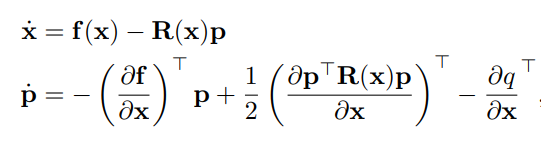 (eqn 75)

(eqn 76)

xp = sym('x',[2*n;1]); 
up = sym('up',[1,1]);

f_sym = f(0,xp(1:4),0);
g= fu(0,xp(1:4));
Df  = jacobian(f_sym ,xp(1:n));
R_x = g*g'; %R(x)
R_0 = g0*g0'; %R(0)

q_x = 1/2*(xp(1)^2+xp(2)^2+xp(3)^2+xp(4)^2); %cost function with Q=1
Dq  = jacobian(q_x,xp(1:n));
DDq = hessian(q_x,xp(1:n));

p = xp(n+1:end);
p1 = jacobian(p'*R_x*p, xp(1:n));

H_sym =  [f_sym-R_x*xp(n+1:end);  -Df'*xp(n+1:end)+0.5.*p1'-Dq']; 
H_sys = matlabFunction(H_sym, 'Vars',{xp(1:2*n),up}); %equation 75

A = [A0, -R_0; -double(DDq), -A0']; %equation 76

## Plot uncontrolled response of Hamiltonain system

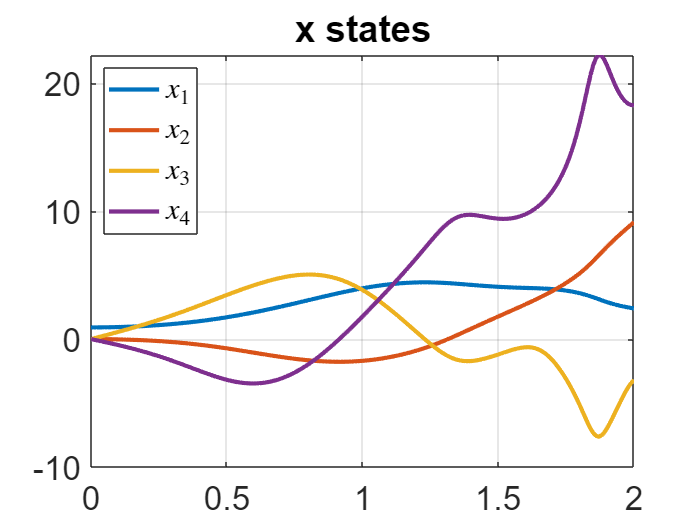

q0 = rand(1);
tSpan = 0:0.01:2; ic = [q0,0,0,0,q0,0,0,0]';
options = odeset('RelTol',1e-9,'AbsTol',1e-300);
[T, x_uncontrolled] = ode45(@(t,x)H_sys(x, 0), tSpan, ic,options);
close all
figure()
%subplot(1,2,1)
plot(T, x_uncontrolled(:,1:n))
grid on;
title('x states')
set(gca,'fontsize',20)
LEG = legend('$x_1$', '$x_2$', '$x_3$','$x_4$','Location','northwest');
set(LEG,'interpreter','latex');

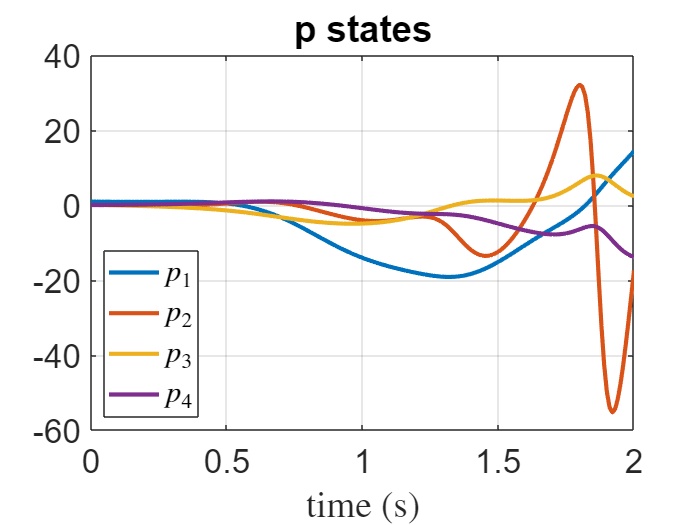

%subplot(1,2,2)
plot(T, x_uncontrolled(:,n+1:2*n))
grid on;
title('p states')
xlabel('time (s) ','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('$p_1$', '$p_2$', '$p_3$','$p_4$','Location','southwest');
set(LEG,'interpreter','latex')

## Parameters setup

Dom1 = [-2*pi 2*pi]; %Domain for q1 q2
Dom2 = [-5 5]; %Domain for q1_dot q2_dot
domain1 = Dom1(2)-Dom1(1);
domain2 = Dom2(2)-Dom2(1);



## Collect random initial conditions

nb_IC = 1e4; %initial coditions
X1 = rand(1,nb_IC)*2*Dom1(2) - Dom1(2); %q1
X2 = X1;
X3 = rand(1,nb_IC)*2*Dom2(2) - Dom2(2); %q1_dot
X4 = X3;
X = [X1; X2; X3; X4]; P = X;
X = [X;P];

## Try some initial conditions and collect X along trajectories 

Skip this if you run the previous section and generated random initial condtions

% numICs = 1000;
% 
% x1range = Dom1; %q1
% x2range = Dom1; %q2
% x3range = Dom2; %q1_dot
% x4range = Dom2; %q2_dot
% tSpan = 0:0.01:1;
% seed = 1;
% rng(seed)
% 
% lenT = length(tSpan);
% 
% X = zeros(lenT, 2*n);
% 
% count = 1;
% for j = 1:100*numICs
%     %randomly start from x1range(1) to x1range(2)
%     x1 = (Dom1(2)-Dom1(1))*rand+Dom1(1);
%     x2 = (Dom1(2)-Dom1(1))*rand+Dom1(1);
%     x3 = (Dom2(2)-Dom2(1))*rand+Dom2(1);
%     x4 = (Dom2(2)-Dom2(1))*rand+Dom2(1);
% 
%     ic = [x1; x2; x3; x4; x1; x2; x3; x4];
%     [T, temp] = ode45(@(t,x)H_sys(x, 0), tSpan, ic);
%     X(1+(count-1)*lenT : lenT + (count-1)*lenT,:) = temp;
%     if count == numICs
%         break
%     end
%     count = count + 1;
% end
% X=X';

## Scale the F(z) and Ez data points

F_z = H_sys(X, 0);
F_z_scaled = [F_z(1:2,:)./domain1;F_z(3:4,:)./domain2; ...
                F_z(5:6,:)./domain1;F_z(7:8,:)./domain2];

E = A;
E_z = E*X;
E_z_scaled = [E_z(1:2,:)./domain1;E_z(3:4,:)./domain2; ...
                E_z(5:6,:)./domain1;E_z(7:8,:)./domain2];

X_scaled = [X(1:2,:)./domain1;X(3:4,:)./domain2; ...
                X(5:6,:)./domain1;X(7:8,:)./domain2;];

## Selet basis functions to approximate h(x)

order = 3; %order poly
[Psi, DPsi] = monomial_basis(order, n); nb_Psi = length(Psi);

$$Psi = \left(\begin{array}{cccccccccccccccccccccccccccccccccc} x_{1} & x_{2} & x_{3} & x_{4} & {x_{4}}^{2} & x_{3}\,x_{4} & {x_{3}}^{2} & x_{2}\,x_{4} & x_{2}\,x_{3} & {x_{2}}^{2} & x_{1}\,x_{4} & x_{1}\,x_{3} & x_{1}\,x_{2} & {x_{1}}^{2} & {x_{4}}^{3} & x_{3}\,{x_{4}}^{2} & {x_{3}}^{2}\,x_{4} & {x_{3}}^{3} & x_{2}\,{x_{4}}^{2} & x_{2}\,x_{3}\,x_{4} & x_{2}\,{x_{3}}^{2} & {x_{2}}^{2}\,x_{4} & {x_{2}}^{2}\,x_{3} & {x_{2}}^{3} & x_{1}\,{x_{4}}^{2} & x_{1}\,x_{3}\,x_{4} & x_{1}\,{x_{3}}^{2} & x_{1}\,x_{2}\,x_{4} & x_{1}\,x_{2}\,x_{3} & x_{1}\,{x_{2}}^{2} & {x_{1}}^{2}\,x_{4} & {x_{1}}^{2}\,x_{3} & {x_{1}}^{2}\,x_{2} & {x_{1}}^{3} \end{array}\right)$$

x1 = sym('x',[2*n,1]);

%remove linear part, principle eigenfunctions
PsiX = Psi(n+1:end); nb_PsiX = length(PsiX);

% term 2 of the basis gamma
X_o_P =  kron(x1(1:n), x1(n+1:2*n)); nb_X_o_P = length(X_o_P);
PsiX_o_P = kron(PsiX, x1(n+1:2*n));% term 3 of the basis gamma

Psi_Gamma = [PsiX; X_o_P; PsiX_o_P]; Nb_G=length(Psi_Gamma);
Gamma = matlabFunction(Psi_Gamma,'Vars',{x1});

Psi_DGamma  = jacobian(Psi_Gamma ,x1);
DGamma = matlabFunction(Psi_DGamma,'Vars',{x1});


## Solve the least squares problem to estimate U

G_z = Gamma(X_scaled);

Df_z = zeros(Nb_G,1);
for i=1:size(X,2)
    Df_z(:,i) = DGamma(X(:,i))*F_z_scaled(:,i);
end

%YALMIP
U_scaled = sdpvar(2*n,Nb_G);
Objective =  norm(U_scaled*Df_z - E*U_scaled*G_z + F_z_scaled - E_z_scaled, 'fro')+ 0.1*norm(U_scaled,1);
Constraints = [];

opt = sdpsettings('solver','gurobi','verbose',2,'cachesolvers',1);
sol = optimize(Constraints,Objective,opt);

Set parameter Username
Academic license - for non-commercial use only - expires 2023-02-11
Warning for adding variables: zero or small (< 1e-13) coefficients, ignored
Gurobi Optimizer version 9.5.0 build v9.5.0rc5 (win64)
Thread count: 4 physical cores, 8 logical processors, using up to 8 threads
Optimize a model with 82823 rows, 82659 columns and 46562094 nonzeros
Model fingerprint: 0x5ecd53e8
Model has 1 quadratic constraint
Coefficient statistics:
  Matrix range     [1e-13, 3e+03]
  QMatrix range    [1e+00, 1e+00]
  Objective range  [1e-01, 1e+00]
  Bounds range     [0e+00, 0e+00]
  RHS range        [2e-09, 1e+01]
         Consider reformulating model or setting NumericFocus parameter
         to avoid numerical issues.
Presolve removed 0 rows and 0 columns (presolve time = 21s) ...
Presolve removed 1 rows and 1 columns (presolve time = 37s) ...
Presolve removed 1 rows and 1 columns (presolve time = 41s) ...
Presolve removed 1 r

U_scaled = value(U_scaled)
save('Procedure2_U_scaled.mat','U_scaled')

## Map U back to the origonal domain

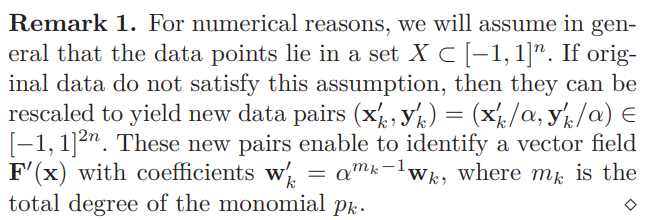

Mauroy, A., & Goncalves, J. (2019). Koopman-based lifting techniques for nonlinear systems identification. *IEEE Transactions on Automatic Control. *(https://arxiv.org/pdf/1709.02003.pdf) 

monomial_degrees = polynomialDegree(PsiX);
U = [];
alpha = [domain1; domain2];

for k = 1:size(monomial_degrees,1)
    m_k = monomial_degrees(k);
    unscale = alpha.^(m_k-1);
    unscale_factor = [unscale;unscale;unscale;unscale];
    U(:,k) = U_scaled(:,k)./unscale_factor;
end
U

## Stable and Unstable Manifolds

[~,  D_lineart,  W_lineart] = eig(A);
[W_linear,  D_linear] = cdf2rdf(W_lineart,D_lineart);

%sort eigenvales and eigenvectors
d = diag(D_linear);
[d, ind] = sort(d,'descend');
D_sorted = D_linear(:,ind);
W = W_linear(:, ind);
Lambda = W'*A*inv(W'); %check that unstable eigenvalues are up
Wu1 = W(1:n,1:n);
Wu2 = W(n+1:2*n,1:n);
J1 = -inv(Wu2')*Wu1';

U11 = U_scaled(1:n, 1:nb_PsiX );
U21 = U_scaled(n+1:2*n, 1:nb_PsiX );
U12 = U_scaled(1:n, 1+nb_PsiX:nb_X_o_P+nb_PsiX);
U22 = U_scaled(n+1:2*n, 1+nb_PsiX:nb_X_o_P+nb_PsiX);
U13 = U_scaled(1:n, 1+nb_PsiX+nb_X_o_P:end);
U23 = U_scaled(n+1:2*n, 1+nb_PsiX+nb_X_o_P:end);

## Estimate B(x)

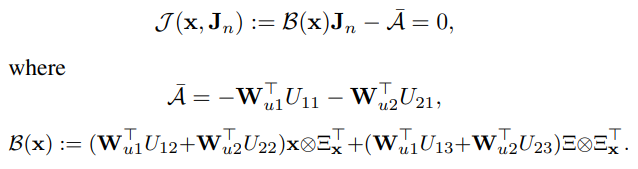

A_bar = -Wu1'*U11 - Wu2'*U21;

%required eigen functions with kron
DPsiX  = jacobian(PsiX ,x1(1:n)); 
X_o_DPsiX = matlabFunction(kron(x1(1:n),DPsiX'), 'Vars',{x1(1:n)});
PsiX_o_DPsiX = matlabFunction(kron(PsiX,  DPsiX'), 'Vars',{x1(1:n)});

Bx = @(x) (Wu1'*U12 + Wu2'*U22)*X_o_DPsiX(x) + (Wu1'*U13 + Wu2'*U23)*PsiX_o_DPsiX(x);

%collect random data points to estimate B(x) eqn 89
Dom3 = [-100 100];
nb_points = 1e8;
data = rand(2*n, nb_points)*2*Dom3(2) - Dom3(2);

B_bar = zeros(n,nb_Psi-n);
for i=1:size(data,2)
    B_bar = B_bar + Bx(data(:,i));
end

B_bar = B_bar/size(data,2)
J2 = pinv(B_bar)*A_bar;

## LQR Controller

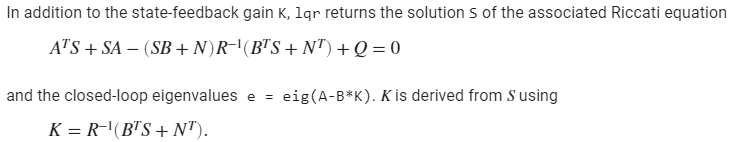

 

Compare matlab's Riccati equation for LQR, we get R_koopman = B_tranpose*inv(R_lqr)*B

Q = eye(n,n); %cost on states
R_lqr = 1;
[K,P,CLP] = lqr(A0,g0,Q,R_lqr);
uLQR = @(x) -K*(x);

## Sanity Check

J1 should be equal to P

J1
P

## HJ-Koopman Controller:

%for koopman control
PsiX_u = matlabFunction(PsiX,'Vars',{x1(1:n)});
DPsiX_u = matlabFunction(DPsiX,'Vars',{x1(1:n)});
uKoop=@(x) -fu(0,x)'*(J1*x + DPsiX_u(x)'*J2*PsiX_u(x));

## Simulation

(change x_initial to simulate response of different initial conditions and plot)

deltaT = 0.1; %step-time
tspan = 0:deltaT:10;
options = odeset('RelTol',1e-9,'AbsTol',1e-10);
x_initial = [0.2,0,0,0];

%LQR
[tspan, xLQR] = ode45(@(t,x)f(t, x, uLQR(x)), tspan, x_initial, options);

if(abs(xLQR(end,1)) && abs(xLQR(end,3)) <=1e-3)
    disp('LQR succuess')
else
    disp('LQR failed')
end
[tspan1, x_Koop] = ode45(@(t,x)f(t, x, uKoop(x)), tspan, x_initial, options);
if(abs(x_Koop(end,1)) && abs(x_Koop(end,3)) <=1e-3)
    disp('HJK succuess')
else
    disp('HJK failed')
end

## Plots

close all
figure(1)
%subplot(2,2,1)
plot(tspan, xLQR)
grid on;
title('LQR')
xlabel('time (s) ','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('$\theta_1$', '$\theta_2$', '$\dot{\theta_1}$','$\dot{\theta_2}$');
set(LEG,'interpreter','latex')
figure(2)
%subplot(2,2,2)
plot(tspan1, x_Koop)
grid on;
title('HJ-Koopman')
xlabel('time (s)','interpreter','latex');
%ylabel('$x_1$,$x_2$','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('$\theta_1$', '$\theta_2$', '$\dot{\theta_1}$','$\dot{\theta_2}$');
set(LEG,'interpreter','latex')
figure(3)
%subplot(2,2,3)
 U_Lqr =zeros(size(xLQR,1),1);
 U_Koop = zeros(size(xLQR,1),1);
for i=1:size(xLQR,1)
    U_Lqr(i) = uLQR(xLQR(i,:)');
    U_Koop(i) =uKoop(x_Koop(i,:)');
end
plot(tspan, U_Lqr, tspan1, U_Koop)
grid on;
title('Input')
xlabel('Time ','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('LQR','HJK');
set(LEG,'interpreter','latex')
title('Control Input of LQR and HJK')
figure(4)
%subplot(2,2,4)
JLQR = cumsum(xLQR(:,1).^2 + xLQR(:,2).^2 + xLQR(:,3).^2+U_Lqr.^2);
Jkoopman =  cumsum(x_Koop(:,1).^2 + x_Koop(:,2).^2 + x_Koop(:,3).^2 +U_Koop.^2 );
plot(tspan, JLQR,tspan, Jkoopman)
grid on;
title('Control Cost of LQR and HJK')
set(gca,'fontsize',20)
LEG =legend( 'LQR','HJK');
ylabel('J','interpreter','latex');
xlabel('Time ','interpreter','latex');
set(LEG,'interpreter','latex')

close all
subplot(2,2,1)
plot(tspan1, xLQR)
grid on; hold on;
%legend('x_1', 'x_2');xlabel('Time')
title('LQR')
xlabel('Time ','interpreter','latex');
%ylabel('$x_1$,$x_2$','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('$\theta_1$', '$\theta_2$', '$\dot{\theta_1}$','$\dot{\theta_2}$');
set(LEG,'interpreter','latex')

subplot(2,2,2)
plot(tspan1, x_Koop)
grid on;
title('HJK')
xlabel('Time','interpreter','latex');
%ylabel('$x_1$,$x_2$','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('$\theta_1$', '$\theta_2$', '$\dot{\theta_1}$','$\dot{\theta_2}$');
set(LEG,'interpreter','latex')

subplot(2,2,3)
 U_Lqr =zeros(size(xLQR,1),1);
 U_Koop = zeros(size(xLQR,1),1);
for i=1:size(xLQR,1)
    U_Lqr(i) = uLQR(xLQR(i,:)');
    U_Koop(i) =uKoop(x_Koop(i,:)');
end
plot(tspan, U_Lqr, tspan1, U_Koop)
grid on;
title('Input')
ylabel('u','interpreter','latex');
xlabel('Time ','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('LQR','HJK');
set(LEG,'interpreter','latex')
title('Control Input')

subplot(2,2,4)
JLQR = cumsum(xLQR(:,1).^2 + xLQR(:,2).^2 + xLQR(:,3).^2+U_Lqr.^2);
Jkoopman =  cumsum(x_Koop(:,1).^2 + x_Koop(:,2).^2 + x_Koop(:,3).^2 +U_Koop.^2 );
plot(tspan, JLQR,tspan, Jkoopman)
grid on;
title('Control Cost')
set(gca,'fontsize',20)
LEG =legend( 'LQR','HJK');
ylabel('J','interpreter','latex');
xlabel('Time ','interpreter','latex');
set(LEG,'interpreter','latex')

## Acrobot f(x)

function f = Acrobot_F(t, x, u)
m1 = 1 ; m2 = 1;
l1 = 1 ; l2 = 1;g = 9.81;
lc1 = l1/2; lc2 = l2/2;
I1 = 1 ;I2 = 1; 
q1 = x(1,:); q2 = x(2,:); dq1 = x(3,:); dq2 = x(4,:);

m11 = I1 + I2 + m2*l1^2 + 2*m2*l1*lc2.*cos(q2);
m12 = I2 + m2*l1*lc2.*cos(q2);
m22 = I2*ones(1,size(x,2));
M = [m11 m12; m12 m22];

C = [-2*m2*l1*lc2.*sin(q2).*dq2.*dq1-m2*l1*lc2.*sin(q2).*dq2.*dq2;
     m2*l1*lc2.*sin(q2).*dq1.*dq1+zeros(1, size(x,2)).*dq2];

% G is negative for q1 = 0  about vertical
% G is positive for q1 = pi about vertical
G = -[m1*g*lc1.*sin(q1) + m2*g.*(l1.*sin(q1)+lc2.*sin(q1+q2));
     m2*g*lc2.*sin(q1+q2)];

dq = [dq1; dq2]; B1 = [zeros(1,size(x,2)); ones(1,size(x,2))];

ddq = M\(B1.*u-C-G);
f = [dq;ddq];
end

## Acrobot g(x)

function g = Acrobot_g(t, x)
m1 = 1 ; m2 = 1;
l1 = 1 ; l2 = 1;g = 9.81;
lc1 = l1/2; lc2 = l2/2;
I1 = 1 ;I2 = 1; 
q1 = x(1,:); q2 = x(2,:); dq1 = x(3,:); dq2 = x(4,:);

m11 = I1+ I2 + m2*l1^2 + 2*m2*l1*lc2*cos(q2);
m12 = I2 + m2*l1*lc2*cos(q2);
m22 = I2;
M = [m11 m12 ; m12 m22];
B1 = [0;1];

g = [0;0; M\(B1)];
end

## Monomial Basis

function [Psi, DPsi] = monomial_basis(deg, dim)
%  [Psi, DPsi] = monomial_basis(deg, dim) returns a monomial basis function and its derivative 
%   There is not a 1 included in Psi, only the linear and higher order terms
%   deg = degree of monomial
%   dim = number of states
k = linspace(2, deg, deg-1);
d = dim;

if (deg == 0)
    Psi = 0;
    for i=1:dim-1
        Psi = [Psi 0];
    end
    DPsi = zeros(dim,dim);
    Psi = Psi';
    
else

    x=sym('x',[d,1]);
    assume(x,'real')
    
    Psi = [x.'];
    for i=1:size(k,2)
        m = nchoosek(k(i)+d-1,d-1); 
        dividers = [zeros(m,1),nchoosek((1:(k(i)+d-1))',d-1),ones(m,1)*(k(i)+d)]; 
        a = diff(dividers,1,2)-1;
        for i = 1:size(a,1)
            Psi = [Psi prod(x.' .^ a(i,:))];
        end
    end
    DPsi = jacobian(Psi,x);
    Trig_terms = [];
    for j=1:dim-2
        Trig_terms = [Trig_terms sin(x(j)) cos(x(j))];
    end

    %Psi = [Psi Trig_terms sin(x(1)+x(2)) cos(x(1)+x(2))]
    Psi
    Psi = Psi';

end

end

## Bernstein Basis

function [Psi,DPsi] = bernstein_basis(order, dim, scale)
%  [Psi, DPsi] = bernstein_basis(deg, dim,scale=0) returns a bernstein basis function and its derivative 
%   There is not a 1 included in Psi, only the linear and higher order terms
%   order = order of bernstein polynomials being fit
%   dim = number of states

if nargin<3
  scale = 0;
end

x=sym('x',[dim,1]);
assume(x,'real')
Psi = [];

if(order==0)
    Psi = 1;
end

for i = 0:order
    m = nchoosek(order,i);
    for j = 1:dim
        %Psi = [Psi; m.*((x(j)+1).^i * (-x(j)).^(order-i))];
        %scale to -2pi to 2pi
        Psi = [Psi; m.*((x(j)+scale).^i * (1-scale-x(j)).^(order-i))];
    end
end

DPsi = jacobian(Psi,x);

end